The first 3 files are for Wesley, the next 3 are for Elvis, and the last 3 are for Melissa. At first we had 6 balls to hit per file, but we later had only 5. All swings were forehand. Data was recorded at 100Hz.

Because there is rotation, it is important to have the orientation data so we can translate back to the global coordinate system.

First, load in all the data files and pick out the individual hits.

There is a signficant amount of extra data at the start because we had to fit the phone into the armband and setup each time. We can remove this off the bat to make it easier to identify the individual hits.

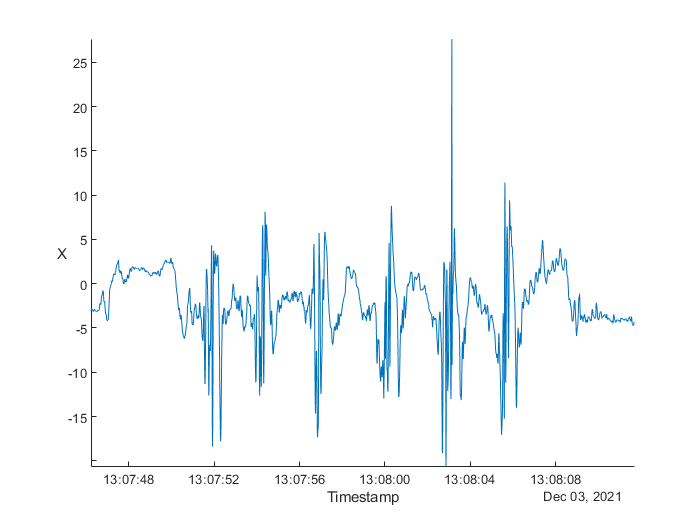

clear;
load data\data4.mat
% plot overything so we can get a sense of what our data looks like
% once we figure it out for one sample, we can trim the others and repeat
%TODO: label
% if we have time it would be cool to ffmpeg the video into frames and then
% plot on top
stackedplot(Acceleration(:,"X"))

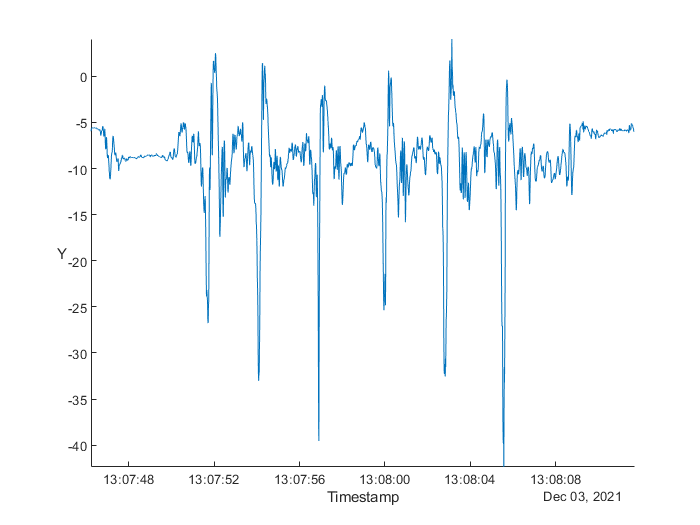

stackedplot(Acceleration(:,"Y"))

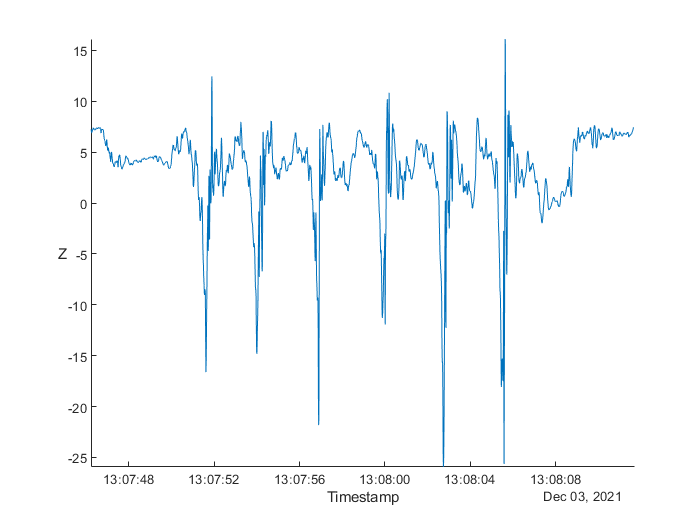

stackedplot(Acceleration(:,"Z"))

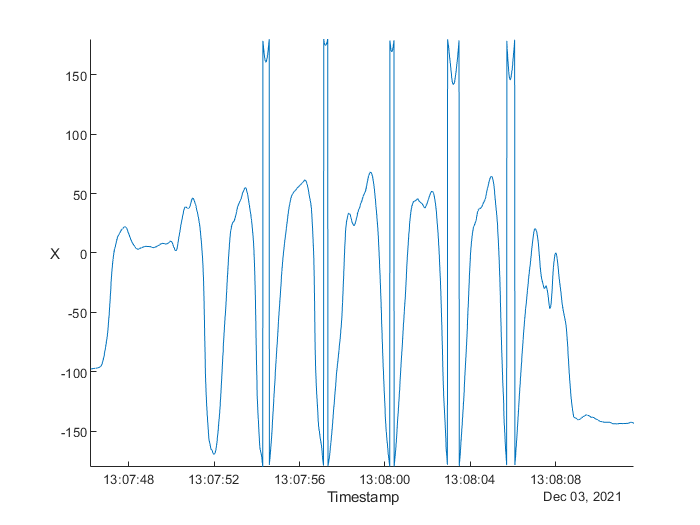

stackedplot(Orientation(:,"X"))

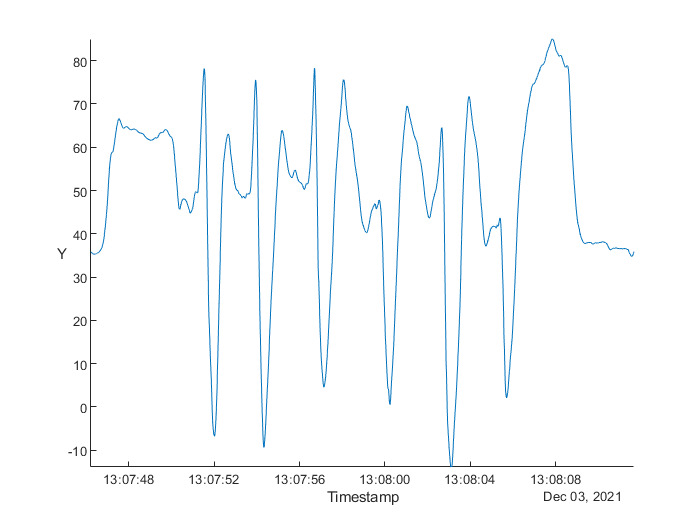

stackedplot(Orientation(:,"Y"))

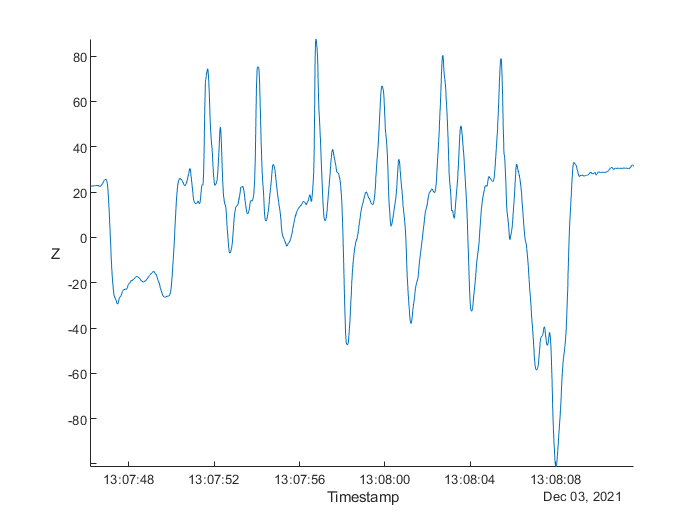

stackedplot(Orientation(:,"Z"))

% might not center it
Accel = normalize_acceleration(Acceleration, Orientation, 9.8, 1/8);

vectors =    -1.1077    0.5872   -1.5465
   -1.1746    0.6587   -1.4656
   -0.8556    0.6026   -1.4573
   -0.7344    0.7006   -1.5972
   -0.8486    0.7619   -1.5921
   -1.0420    0.7625   -1.5488
   -1.0584    0.7351   -1.6253
   -1.0596    0.6591   -1.7534
   -1.1740    0.6573   -1.8036
   -1.3283    0.6665   -1.8565


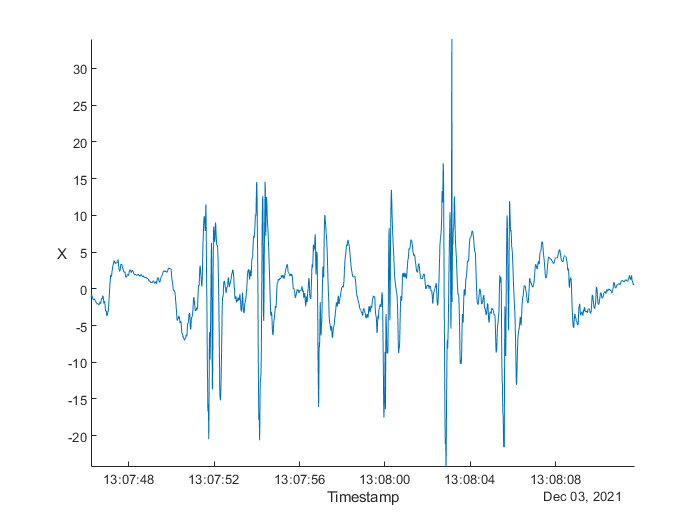

stackedplot(Accel(:,"X"))

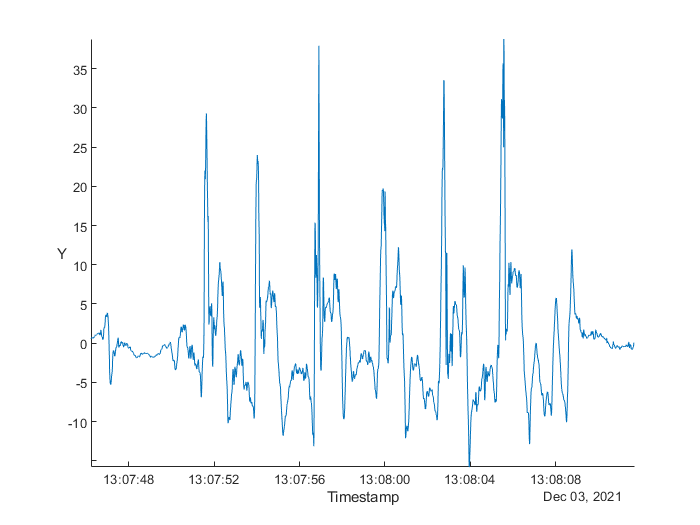

stackedplot(Accel(:,"Y"))

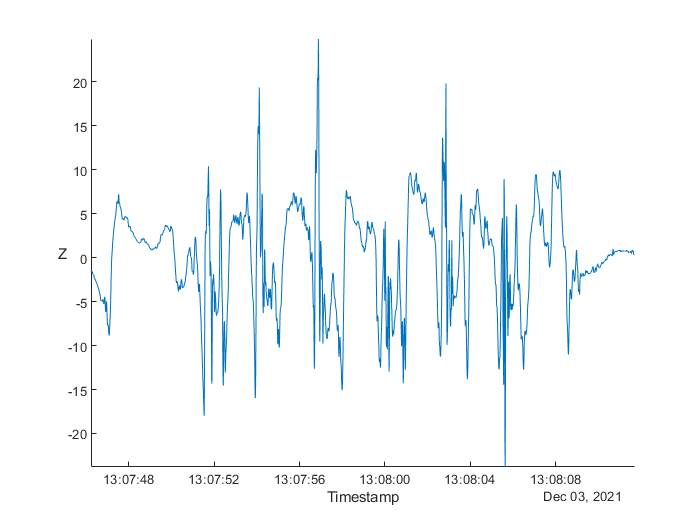

stackedplot(Accel(:,"Z"))

% remove acceleration due to gravity
Velocity = velocity(Accel);
vel = Velocity.Variables;
max(abs(vel(:, 1)))

ans = 4.3170

max(abs(vel(:, 2)))

ans = 6.9699

max(abs(vel(:, 3)))

ans = 5.5768

speed = vecnorm(vel')';

speed =          0
    0.0199
    0.0388
    0.0570
    0.0762
    0.0960
    0.1165
    0.1376
    0.1596
    0.1826


max(speed)

ans = 7.8603

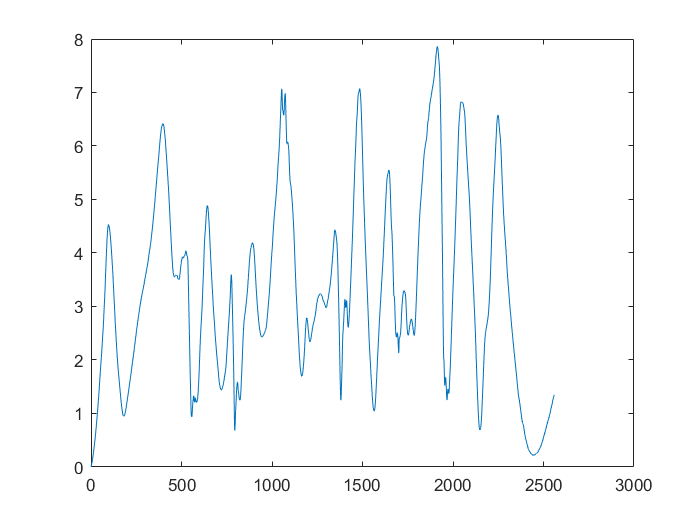

plot(speed)

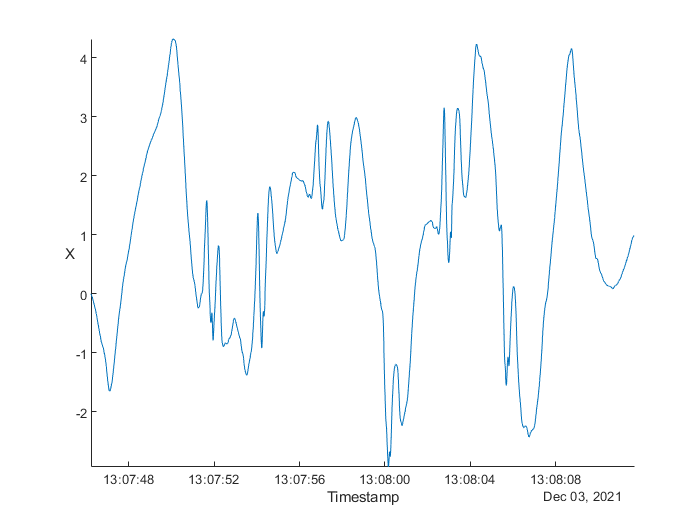

stackedplot(Velocity(:,"X"))

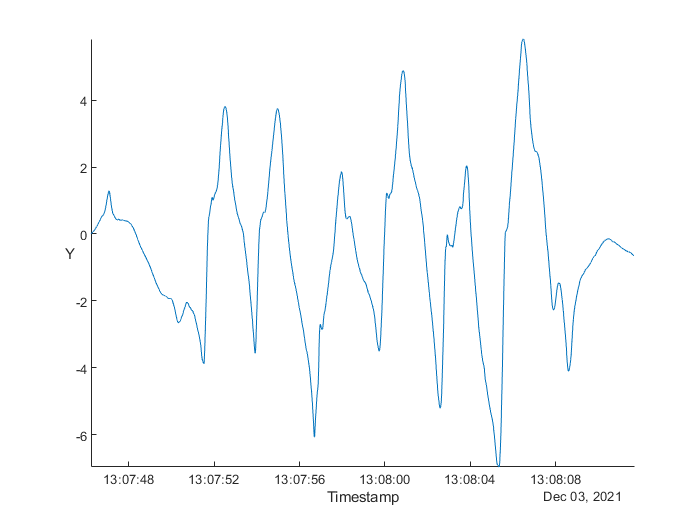

stackedplot(Velocity(:,"Y"))

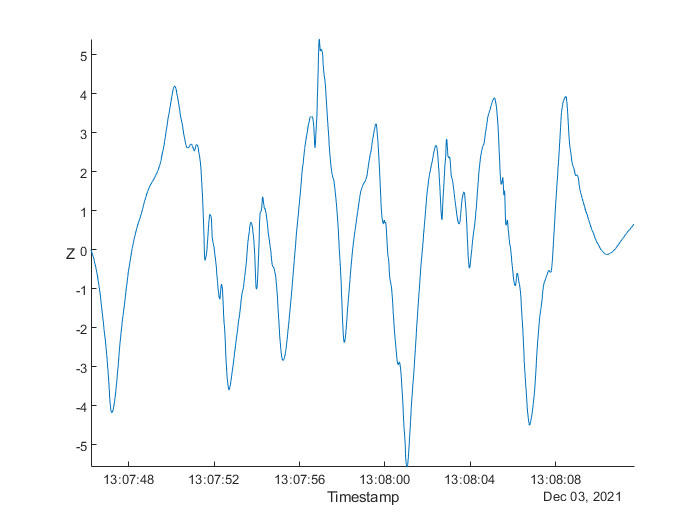

stackedplot(Velocity(:,"Z"))

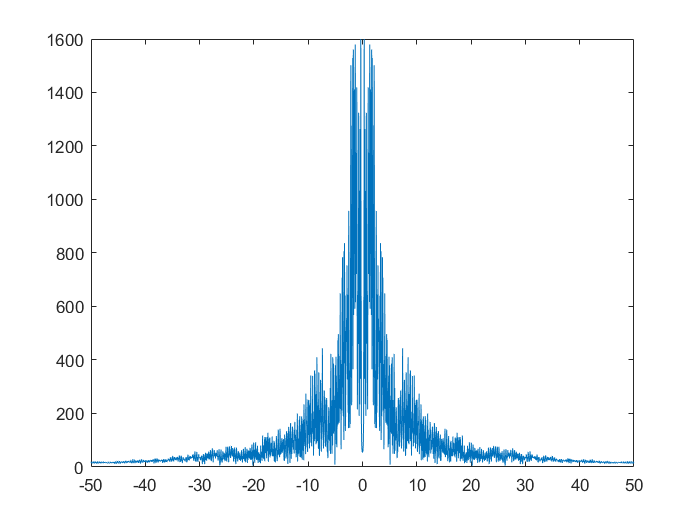

% fft now that we have all our positional information
Fs = 100; % 100Hz (its not perfect, but this is as good as we can do)
a_mat = Accel.Variables;
y = a_mat(:, 1);
%y=y-mean(y);
%y = detrend(y,'constant');
N = length(y);
freqs = linspace(-Fs*pi , Fs*(pi - 2*pi/N), N) + Fs*pi/N*mod(N,2);
freqs = freqs * (1/(2*pi));
freq_domain = fftshift(fft(y));
filter_out = freqs == 0; %(freqs >= -Fs/2 & freqs <= -Fs/4) | (freqs >= Fs/4 & freqs <= Fs/2);
freq_domain_filtered = freq_domain;
freq_domain_filtered(filter_out) = freq_domain(filter_out)/10;
% and back again
filtered = ifft(ifftshift(freq_domain_filtered));
figure()
title("raw")
plot(freqs, abs(freq_domain_filtered));

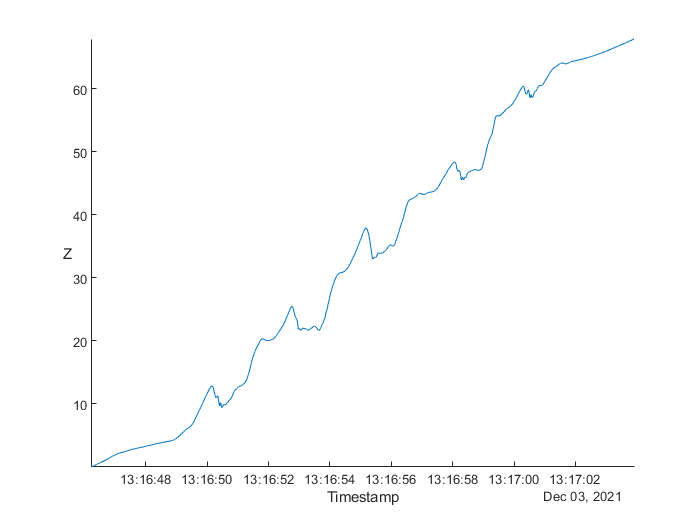

% visualize the orientation over time
figure();
% current position
x = 0; y = 0; z = 0;
% plot the orientation vectors
BASIS = [ 
    1 0 0;
    0 1 0;
    0 0 1;
];
points = height(Acceleration);
position = [x, y, z];
orientation_matrix = Orientation.Variables;
for idx=1:3:points % speedup to keep animation relatime (remove later!)
    R = rot(orientation_matrix(idx, :));
    V = R * BASIS;
    hold on;
    quiver3(position(1), position(2), position(3), V(1,1), V(1,2), V(1,3), 0, 'r');
    quiver3(position(1), position(2), position(3), V(2,1), V(2,2), V(2,3), 0, 'b');
    quiver3(position(1), position(2), position(3), V(3,1), V(3,2), V(3,3), 0, 'g');
    hold off;
    axis equal;
    xlim([-1, 1]);
    ylim([-1, 1]);
    zlim([-1, 1]);
    drawnow limitrate; %run at 20fps, remove this for exporting to video
    clf;
end

% FIRST project onto the global coordinate system
Accel = normalize_acceleration(Acceleration, Orientation);

Index in position 1 exceeds array bounds (must not exceed 2040).

Error in Analysis>normalize_acceleration (line 75)
        vectors(i, :) = vector * rot(orientation_vectors(i, :));

Velocity = velocity(Accel);
vel = Velocity.Variables;
max(abs(vel(:, 1)))
% integrate for velocity
% integrate again for position

%TODO: visualize the position and velocity and acceleration vectors


% maybe looking at upwards acceleration would allow us to evaluate spin?
% can probably get angle at impact
% maybe could get some sample data to show we can score low for having a
% really bad angle

% https://www.mathworks.com/matlabcentral/fileexchange/23629-export_fig
% might work for saving as a transparent overlay for video
% otherwise can just live with the white background

function R = rot(angle)
    R = rotz(angle(3)) * roty(angle(2)) * rotx(angle(1));
end

% take the acceleration and orientation data and transform the axis to the
% global system
function A = normalize_acceleration(accel, orient, g, fpass)
    % unfortunately because orientation is changing we have to transform
    % row by row instead of just using a single matrix multiplication
    vectors = accel.Variables;
    orientation_vectors = orient.Variables;
    for i=1:height(accel)
        vector = vectors(i, :);
        % now that we don't need it anymore overwrite it
        vectors(i, :) = vector * rot(orientation_vectors(i, :));
    end
    Timestamp = accel.Timestamp; % get the times for creating a new timetable
    % remove gravity
    vectors(:, 3) = vectors(:, 3) + g;
    % because the person may be drifting (moving overall)
    % and we expect the arm position to more or less return to the start
    % we can detrend the data to remove this hidden linear term
    % we are just using a high pass filter to do so
    vectors = filter_acceleration(vectors, fpass)
    A = timetable(Timestamp, vectors(:, 1), vectors(:, 2), vectors(:, 3), 'VariableNames',{'X','Y', 'Z'});
end

function A =  filter_acceleration(accel_mat, fpass)
    % high pass filter on each dimension
    accel_mat(:, 1) = highpass(accel_mat(:, 1), fpass, 100);
    accel_mat(:, 2) = highpass(accel_mat(:, 2), fpass, 100);
    accel_mat(:, 3) = highpass(accel_mat(:, 3), fpass, 100);
    A = accel_mat;
end

function V = velocity(accel)
    % integrate
    vectors = accel.Variables;
    Timestamp = accel.Timestamp;
    t = seconds(accel.Timestamp - accel.Timestamp(1));
    integrated = cumtrapz(t, vectors);
    V = timetable(Timestamp, integrated(:, 1), integrated(:, 2), integrated(:, 3), 'VariableNames',{'X','Y', 'Z'});
end